# Thevenin and Norton Equivalents Lab

In this lab, you will derive Thevenin and Norton equivalents by hand and using Simscape. 

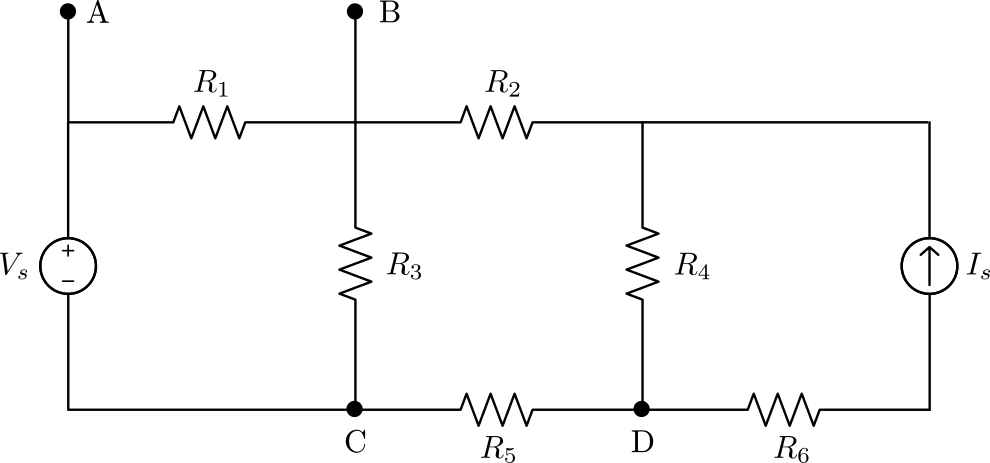

*Circuit to analyze.*

The resistances and voltages are

    
$$\begin{array}{l}
R_1 = 5 \ \Omega
\\
R_2 = 15 \ \Omega
\\
R_3 = 10 \ \Omega
\\
R_4 = 20 \ \Omega
\\
R_5 = 15 \ \Omega
\\
R_6 = 5 \ \Omega
\end{array}$$
         
$$\begin{array}{l}
V_{s} = 24 \ \text{V}
\\
I_{s} = 25 \ \text{mA}
\end{array}$$


### Part 1. Solve for the Thevenin equivalent between A and B

To solve for the Thevenin equivalent between terminals A and B, perform the following steps.

**Task 1.** There is no load resistor to be removed ($R_2$ should remain), so you can skip the first step of the procedure.

**Task 2.** Compute the equivalent resistance of the circuit, $R_{THEV}$. To do so, short the voltage sources and open circuit the current sources. Record your answer below.

RthevAB = 3.125

RthevAB = 3.1250

**Task 3. **Identify the Thevenin equivalent voltage in the original circuit by computing the voltage drop between A and B. Use nodal analysis to identify the node voltages. Write your code in the space below to construct the coefficient and compute the voltage.

% Write your code here
M = [-11/30,   0,  1/15;
     1/15,  1/20, -7/60;
     0,    -7/60,  1/20];
b = [-24/5; -0.025; 0.025];
V = M\b;
Vb = V(1);

VthevAB = 24-Vb

VthevAB = 8.9687

**Question 1.** If a 6 $\Omega$ load resistor is placed between A and B, what will the current through it be? Use the Thevenin equivalent to identify the value. Record your answer below.

IloadAB = VthevAB/(6 + RthevAB)

IloadAB = 0.9829

### Part 2. Validate your Thevenin equivalent using Simscape

You can validate your result by building the circuit in Simscape and then measuring the relevant values. Perform the following steps to validate your work.

**Task 1. **Open the starter model: [TheveninNortonCircuit.slx](matlab: TheveninNortonCircuit). Build the circuit in Simscape and set the resistor and source values.

**Task 2.** Short circuit the voltage source and comment out the voltage source and current source blocks (right-click the block and select **Comment Out**). Then, measure the Thevenin equivalent resistance using the multimeter in ohms. Record the value below. Does it match $R_{THEV}$ that you recorded above?

RthevAB_measured = 3.13

RthevAB_measured = 3.1300

**Task 3.** Uncomment the sources and reconfigure the model so that it matches the original circuit. Then, measure the voltage between nodes A and B using the multimeter in volts. Does it match the Thevenin equivalent voltage you measured above?

VthevAB_measured = 8.97

VthevAB_measured = 8.9700

**Task 4.** Add a 6 Ohm load resistor by copying and pasting one of the existing resistors. Then, connect it to the circuit. Measure the current through the load resistor using the multimeter. Record the value below in amps. Does it match the value you identified above?

IloadAB_measured = 0.98

IloadAB_measured = 0.9800

**Task 5. **Delete the load resistor to prepare for the next part of the lab.

### Part 3. Create a Norton equivalent between nodes C and D

You can create an equivalent circuit between any two nodes. In this part of the lab, you will identify the Norton equivalent circuit with respect to nodes C and D. The Norton equivalent will be identified by taking measurements in the Simscape model, rather than deriving the values by hand. $R_5$ will be treated as the load resistor.

**Task 1. **Open the model: [TheveninNortonCircuit.slx](matlab: TheveninNortonCircuit). Ensure that the circuit matches the original circuit.

**Task 2. **Comment out the load resistor, $R_5$, as shown in the diagram below, so that you can measure the the Norton equivalent values.

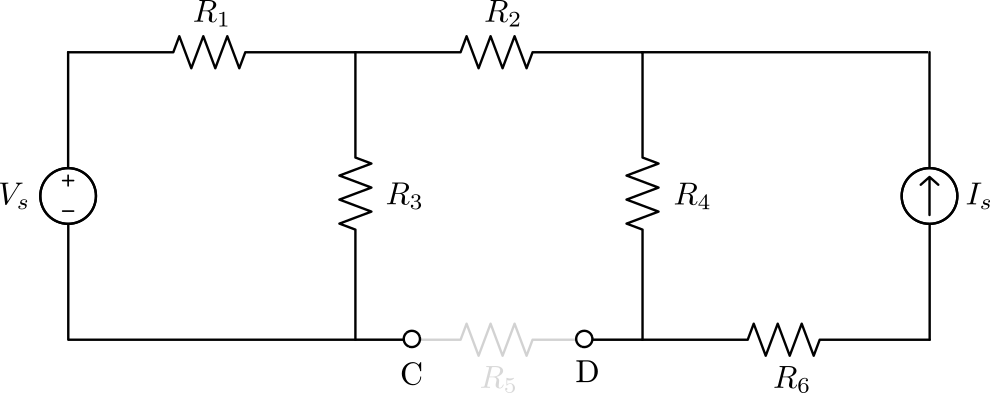

*Circuit used to construct the Norton equivalent with respect to terminals C and D*

**Task 3. **Short circuit the voltage source and comment out the voltage source and current source blocks (right-click the block and select **Comment Out**). Then, measure the Thevenin equivalent resistance using the multimeter. Record the value below. 

RthevCD = 38.34

RthevCD = 38.3400

**Task 4.** Uncomment the sources and reconfigure the model so that it matches the circuit shown in **Task 2**. Then, measure the short-circuit current between terminals C and D using the multimeter. Record the value below in amps.

InortCD = -0.40

InortCD = -0.4000

**Task 5. **Replace the 15 ohm load resistor in the circuit and measure the current through it. Record the value below in amps.

IloadCD = -0.29

IloadCD = -0.2900

### Part 4. Construct the Thevenin equivalent from the Norton equivalent

With the Norton equivalent identified with respect to nodes C and D, you can easily compute the Thevenin equivalent.

**Task 1. **Using the values of `RthevCD` and `InortCD `you recorded in the previous part, compute the Thevenin equivalent voltage between C and D.

VthevCD = -0.4*38.34

VthevCD = -15.3360

**Task 2. **Consider the Thevenin equivalent circuit (with respect to the terminals C and D) with a 15 $\Omega$ load resistor as shown in the diagram below.

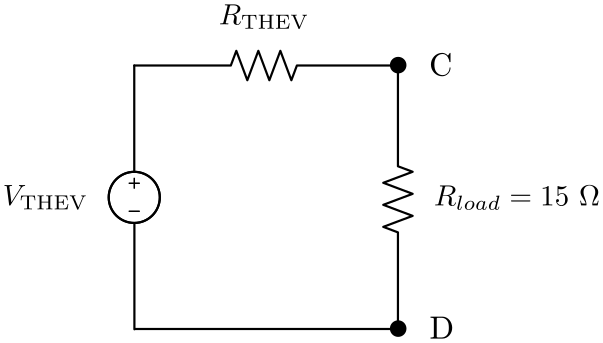

What is the current through the load resistor in amps (record your answer below)? Does it match the measurement in the circuit in part 3?

IloadCD_thevenin = -15.336/(15 + 38.34)

IloadCD_thevenin = -0.2875